# Sesión 4: Sistemas de ecuaciones no lineales

Método Gráfico

- Graficando curvas de nivel

Punto Fijo para sistemas

- Implementación vectorial

- Criterio de convergencia

Newton para sistemas

- Implementación vectorial

## Método gráfico

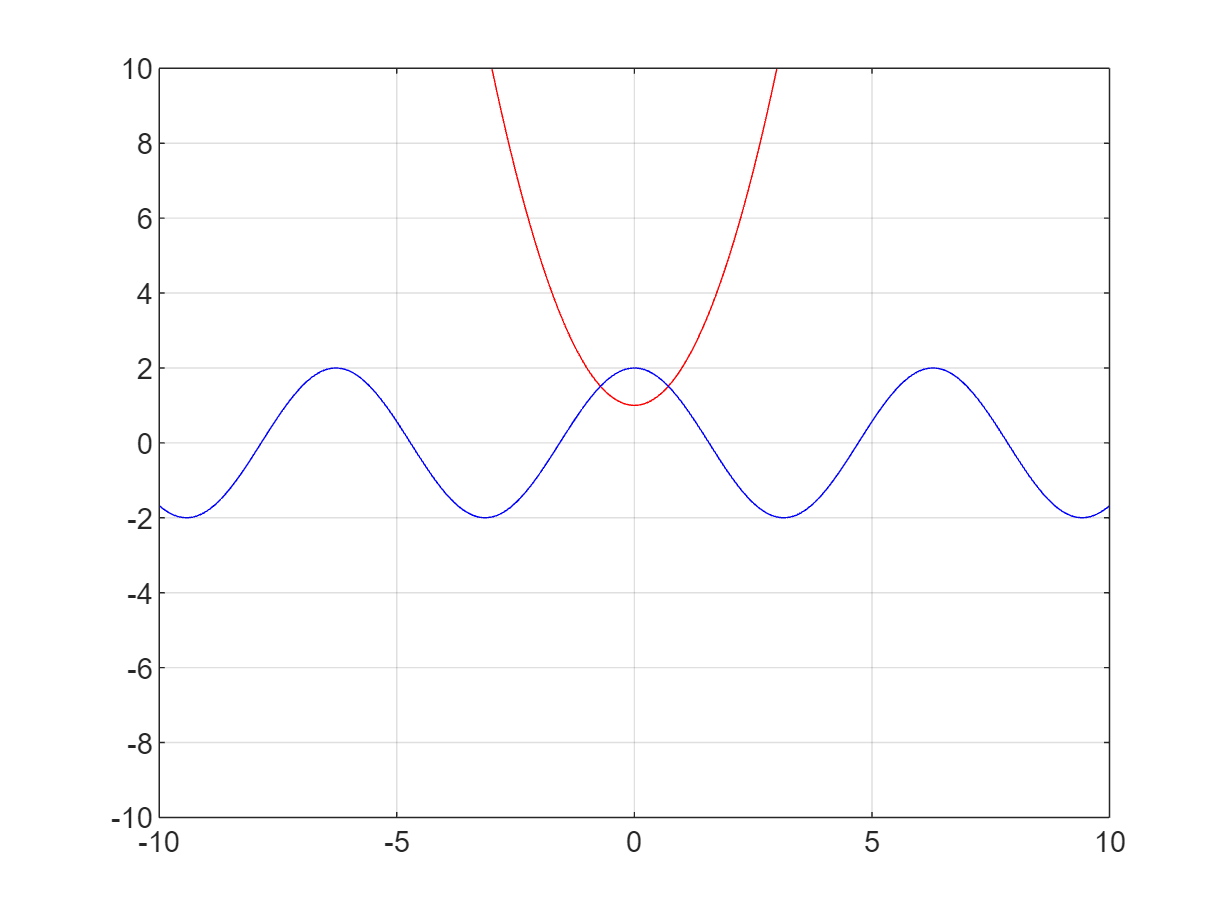

clf
x=-10:0.1:10;
y=-10:0.1:10;
[X,Y]=meshgrid(x,y);
f1= X.^2+1-Y;
f2= 2*cos(X)-Y;
figure(1);
contour(X,Y,f1,[0,0],'r'); hold on;
contour(X,Y,f2,[0,0],'b');
grid on; hold off;

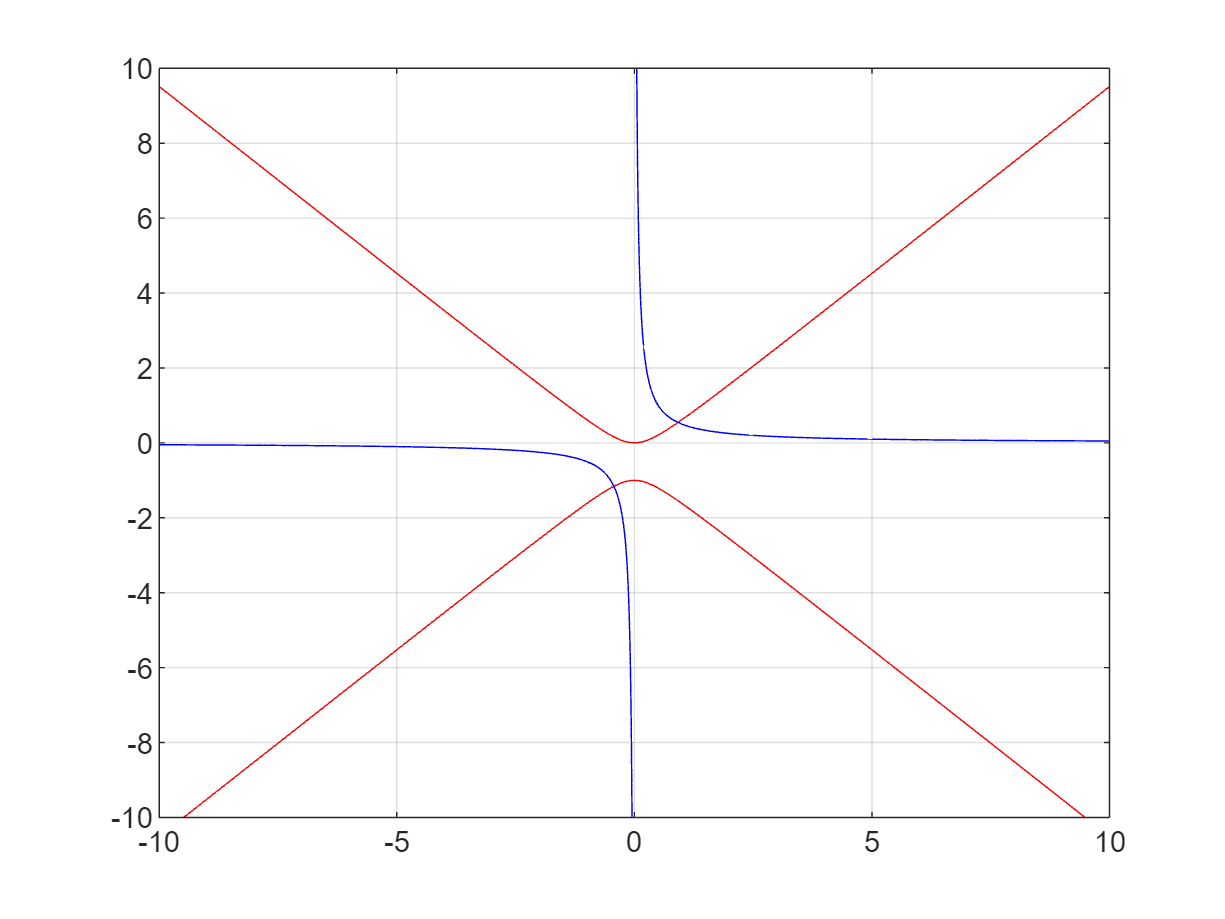

clf
x=-10:0.1:10;
y=-10:0.1:10;
[X,Y]=meshgrid(x,y);
f1= X.^2-Y.^2-Y;
f2= 2.*X.*Y-1;
figure(2);
contour(X,Y,f1,[0,0],'r'); hold on;
contour(X,Y,f2,[0,0],'b');
grid on; hold off;

- Se observa dos soluciones del sistema de ecuaciones en ambos casos

- Esto permite plantear una primera aproximación $(x^0,y^0)$ para luego aplicar el método de Newton o Punto Fijo para sistemas de ecuaciones no lineales. 

## Punto Fijo para sistemas

### Implementación vectorial

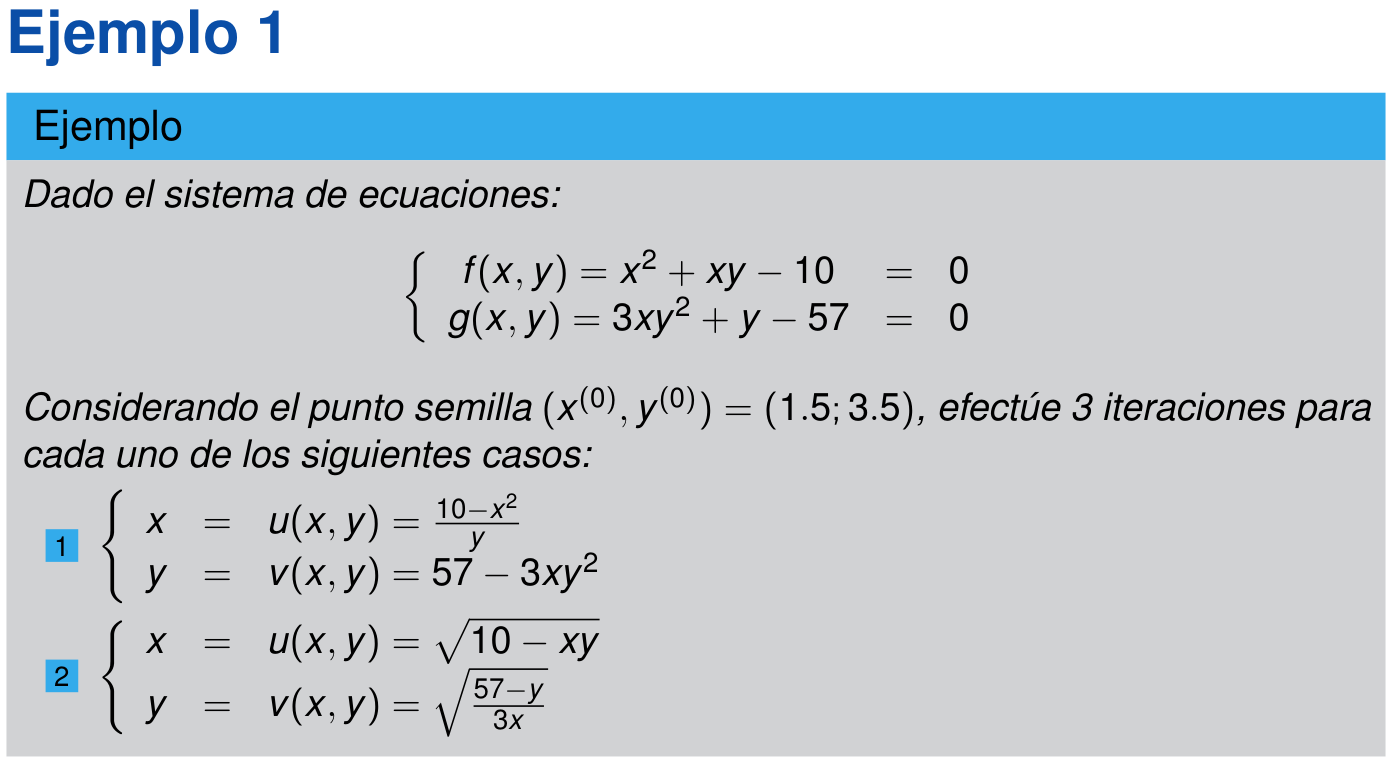

Vamos a desarrollar el segundo despeje

Planteamos vectorialmente: sea $\mathbf{x}=\left[ \begin{array}{c}
x \\
y 
\end{array} \right]$ de modo que $\mathbf{x}(1)=x, \mathbf{x}(2)=y$

Luego, el problema a resolver es $\mathbf{x}=G(\mathbf{x})=
\left[ \begin{array}{c}
u(x,y) \\
v(x,y) 
\end{array} \right]  = 
\left[ \begin{array}{c}
\sqrt{10-xy} \\
\sqrt{\frac{57-y}{3x}} 
\end{array} \right] $ 

x0=[1.5;
    3.5]

x0 =     1.5000
    3.5000


G = @(x) [sqrt(10-x(1)*x(2)); 
    sqrt((57-x(2))/(3*x(1)))]

G = function_handle with value:
    @(x)[sqrt(10-x(1)*x(2));sqrt((57-x(2))/(3*x(1)))]


syms x y
G_sym = G([x;y])

$$G\_sym = \left(\begin{array}{c} \sqrt{10-x\,y}\\ \sqrt{-\frac{y-57}{3\,x}} \end{array}\right)$$

G(x0)

ans =     2.1794
    3.4480


format short
Maxiter=4;
z=pfijoVec(G,x0,Maxiter);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),...
    'VariableNames',{'k','x^(k)','y^(k)','error'}))

    k    x^(k)     y^(k)      error 
    _    ______    ______    _______

    0       1.5       3.5        NaN
    1    2.1794     3.448    0.19705
    2    1.5765    2.8619     0.2107
    3    2.3427    3.3834    0.22648
    4      1.44     2.762    0.32682



- *El método no converge: la columna de errores relativos no decrece hacia 0.*

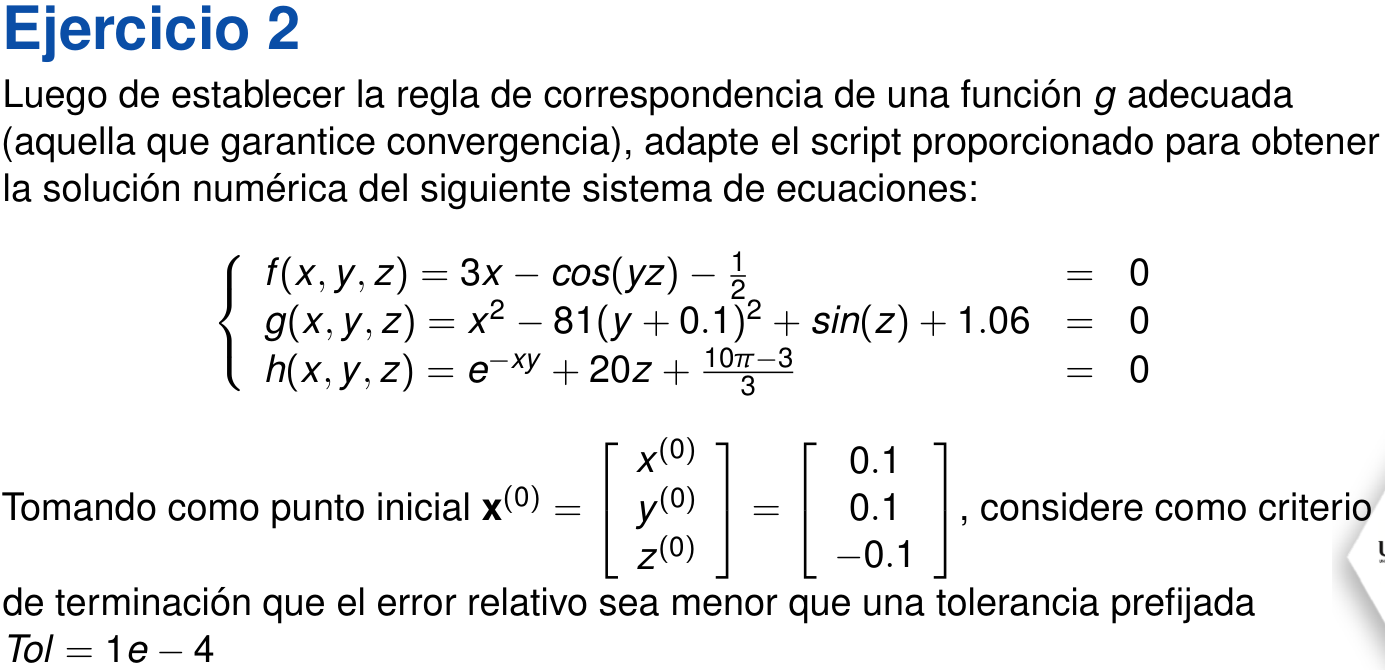

Primero despejamos, $x=\frac{1}{3} \left( cos(yz)+\frac{1}{2}\right)$, $y=\sqrt{\frac{x^2+\sin(z)+1.06}{81}}-0.1$, $z=\frac{1}{20}\left(-e^{-xy}-\frac{10\pi-3}{3}\right)$

Planteamos vectorialmente: 

sea $\mathbf{x}=\left[ \begin{array}{c}
x \\
y \\
z
\end{array} \right]$ de modo que el problema es $\mathbf{x}=G(\mathbf{x})=
\left[ \begin{array}{c}
u(x,y,z) \\
v(x,y,z) \\
w(x,y,z) \\
\end{array} \right]  = 
\left[ \begin{array}{c}
\frac{1}{3} \left( cos(yz)+\frac{1}{2}\right) \\
\sqrt{\frac{x^2+\sin(z)+1.06}{81}}-0.1 \\
\frac{1}{20}\left(-e^{-xy}-\frac{10\pi-3}{3}\right)
\end{array} \right] $ 

x0=[0.1;
    0.1;
    -0.1]

x0 =     0.1000
    0.1000
   -0.1000


G = @(x) [(cos(x(2)*x(3))+0.5)/3; 
    sqrt((x(1)^2+sin(x(3))+1.06)/81)-0.1; 
    (-exp(-x(1)*x(2))-(10*pi-3)/3)/20]

G = function_handle with value:
    @(x)[(cos(x(2)*x(3))+0.5)/3;sqrt((x(1)^2+sin(x(3))+1.06)/81)-0.1;(-exp(-x(1)*x(2))-(10*pi-3)/3)/20]


G(x0)

ans =     0.5000
    0.0094
   -0.5231


format long
Maxiter=8;
z=pfijoVec(G,x0,Maxiter);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),...
    'VariableNames',{'k','x^(k)','y^(k)','z^(k)','error'}))

    k          x^(k)                 y^(k)                  z^(k)                  error        
    _    _________________    ____________________    __________________    ____________________

    0                  0.1                     0.1                  -0.1                     NaN
    1    0.499983333472222     0.00944114960371335    -0.523101267285757       0.808832426426961
    2    0.499995934919313    2.55677467667498e-05    -0.523363310908805      0.0179905271552122
    3    0.499999999970157    1.23367203633679e-05    -0.523598136413912    0.000448484226310316
    4    0.499999999993046    3.41679062543232e-08    -0.523598467181241    2.34961582743806e-05
    5                  0.5    1.64870404134598e-08    -0.523598774744101    5.87401795067975e-07
    6                  0.5    4.56640003587694e-11   

**Ejercicio**: Completar la implementación del punto fijo para sistemas dado un nivel de tolerancia.

### Criterio de convergencia

Debemos verificar que se cumplen las 3 condiciones (para cada $u,v,w$)


$$\left|\frac{\partial u}{\partial x} (x^0,y^0,z^0) \right| + \left|\frac{\partial u}{\partial y} (x^0,y^0,z^0) \right| + \left|\frac{\partial u}{\partial z} (x^0,y^0,z^0) \right| <1$$



$$\left|\frac{\partial v}{\partial x} (x^0,y^0,z^0) \right| + \left|\frac{\partial v}{\partial y} (x^0,y^0,z^0) \right| + \left|\frac{\partial v}{\partial z} (x^0,y^0,z^0) \right| <1$$



$$\left|\frac{\partial w}{\partial x} (x^0,y^0,z^0) \right| + \left|\frac{\partial w}{\partial y} (x^0,y^0,z^0) \right| + \left|\frac{\partial w}{\partial z} (x^0,y^0,z^0) \right| <1$$


clear
G = @(x) [(cos(x(2)*x(3))+0.5)/3; 
    sqrt((x(1)^2+sin(x(3))+1.06)/81)-0.1; 
    (-exp(-x(1)*x(2))-(10*pi-3)/3)/20];
syms x y z
G_sym = G([x;y;z])

$$G\_sym = \left(\begin{array}{c} \frac{\cos\left(y\,z\right)}{3}+\frac{1}{6}\\ \sqrt{\frac{x^{2}}{81}+\frac{\sin\left(z\right)}{81}+\frac{53}{4050}}-\frac{1}{10}\\ -\frac{{\mathrm{e}}^{-x\,y}}{20}-\frac{1066449634653811}{2251799813685248} \end{array}\right)$$

u = G_sym(1)

$$u = \frac{\cos\left(y\,z\right)}{3}+\frac{1}{6}$$

v = G_sym(2)

$$v = \sqrt{\frac{x^{2}}{81}+\frac{\sin\left(z\right)}{81}+\frac{53}{4050}}-\frac{1}{10}$$

w = G_sym(3)

$$w = -\frac{{\mathrm{e}}^{-x\,y}}{20}-\frac{1066449634653811}{2251799813685248}$$

abs(diff(u,x))+abs(diff(u,y))+abs(diff(u,z))

$$ans = \frac{\left|z\,\sin\left(y\,z\right)\right|}{3}+\frac{\left|y\,\sin\left(y\,z\right)\right|}{3}$$

double(subs(abs(diff(u,x))+abs(diff(u,y))+abs(diff(u,z)),...
    [x,y,z],[0.1,0.1,-0.1]))

ans =      6.666555556111110e-04


abs(diff(u,x))+abs(diff(u,y))+abs(diff(u,z))

$$ans = \frac{\left|z\,\sin\left(y\,z\right)\right|}{3}+\frac{\left|y\,\sin\left(y\,z\right)\right|}{3}$$

double(subs(abs(diff(u,x))+abs(diff(u,y))+abs(diff(u,z)),...
    [x,y,z],[0.1,0.1,-0.1]))

ans =      6.666555556111110e-04


abs(diff(v,x))+abs(diff(v,y))+abs(diff(v,z))

$$ans = \frac{\left|\cos\left(z\right)\right|}{162\,\sqrt{\left|\frac{x^{2}}{81}+\frac{\sin\left(z\right)}{81}+\frac{53}{4050}\right|}}+\frac{\left|x\right|}{81\,\sqrt{\left|\frac{x^{2}}{81}+\frac{\sin\left(z\right)}{81}+\frac{53}{4050}\right|}}$$

double(subs(abs(diff(v,x))+abs(diff(v,y))+abs(diff(v,z)),...
    [x,y,z],[0.1,0.1,-0.1]))

ans =    0.067402151276552


abs(diff(w,x))+abs(diff(w,y))+abs(diff(w,z))

$$ans = \frac{{\mathrm{e}}^{-\mathrm{real}\left(x\,y\right)}\,\left|x\right|}{20}+\frac{{\mathrm{e}}^{-\mathrm{real}\left(x\,y\right)}\,\left|y\right|}{20}$$

double(subs(abs(diff(w,x))+abs(diff(w,y))+abs(diff(w,z)),...
    [x,y,z],[0.1,0.1,-0.1]))

ans =    0.009900498337492


- En este caso se cumple el criterio de convergencia

- *OBS: El criterio de convergencia no siempre es concluyente y se debe realizar las iteraciones del algoritmo para ver si converge o no*

## Newton para sistemas

### Implementación vectorial

Planteamos vectorialmente: 

sea $\mathbf{x}=\left[ \begin{array}{c}
x \\
y \\
z
\end{array} \right]$ de modo que el problema es $F(\mathbf{x})=\left[ \begin{array}{c}
3x-cos(yz)-\frac{1}{2} \\
x^2-81(y+0.1)^2+\sin(z)+1.06 \\
e^{-xy}+20z+\frac{10\pi-3}{3}
\end{array} \right] = 
\left[ \begin{array}{c}
0 \\
0 \\
0
\end{array} \right]$ 

x0=[0.1;
    0.1;
    -0.1]

x0 =    0.100000000000000
   0.100000000000000
  -0.100000000000000


F = @(x) [3*x(1)-cos(x(2)*x(3))-0.5; 
    x(1)^2-81*(x(2)+0.1)^2+sin(x(3))+1.06; 
    exp(-x(1)*x(2))+20*x(3)+(10*pi-3)/3]

F = function_handle with value:
    @(x)[3*x(1)-cos(x(2)*x(3))-0.5;x(1)^2-81*(x(2)+0.1)^2+sin(x(3))+1.06;exp(-x(1)*x(2))+20*x(3)+(10*pi-3)/3]


F(x0)

ans =   -1.199950000416665
  -2.269833416646829
   8.462025345715146


syms x [3 1]
F_sym = F(x)

$$F\_sym = \left(\begin{array}{c} 3\,x_{1}-\cos\left(x_{2}\,x_{3}\right)-\frac{1}{2}\\ \sin\left(x_{3}\right)-81\,{\left(x_{2}+\frac{1}{10}\right)}^{2}+{x_{1}}^{2}+\frac{53}{50}\\ 20\,x_{3}+{\mathrm{e}}^{-x_{1}\,x_{2}}+\frac{5332248173269055}{562949953421312} \end{array}\right)$$

J_sym = jacobian(F_sym)

$$J\_sym = \left(\begin{array}{ccc} 3 & x_{3}\,\sin\left(x_{2}\,x_{3}\right) & x_{2}\,\sin\left(x_{2}\,x_{3}\right)\\ 2\,x_{1} & -162\,x_{2}-\frac{81}{5} & \cos\left(x_{3}\right)\\ -x_{2}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & -x_{1}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & 20 \end{array}\right)$$

J = matlabFunction(J_sym) % J tiene argumentos como escalares (no queremos esto)

J = function_handle with value:
    @(x1,x2,x3)reshape([3.0,x1.*2.0,-x2.*exp(-x1.*x2),x3.*sin(x2.*x3),x2.*-1.62e+2-8.1e+1./5.0,-x1.*exp(-x1.*x2),x2.*sin(x2.*x3),cos(x3),2.0e+1],[3,3])


J = matlabFunction(J_sym, 'Vars',{x}); % J tiene 1 solo argumento como vector (OK)
J(x0) % Matriz Jacobiana

ans =    3.000000000000000   0.000999983333417  -0.000999983333417
   0.200000000000000 -32.399999999999999   0.995004165278026
  -0.099004983374917  -0.099004983374917  20.000000000000000


inv(J(x0)) % Inversa de la matriz Jacobiana

ans =    0.333333183973692   0.000010238518631   0.000016157012988
   0.002108606838122  -0.030868825519714   0.001535835927053
   0.001660520446129  -0.000152757694651   0.050007682751761


Implementaciones vectoriales de Newton para sistemas

format long
Maxiter=3;
z=newtonVec(F,x0,Maxiter);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),...
    'VariableNames',{'k','x^(k)','y^(k)','z^(k)','error'}))

    k          x^(k)                 y^(k)                  z^(k)                  error       
    _    _________________    ____________________    __________________    ___________________

    0                  0.1                     0.1                  -0.1                    NaN
    1    0.499869672926428      0.0194668485374181    -0.521520471935831      0.808252973025565
    2    0.500014240164219     0.00158859137029389    -0.523556964347638      0.034147682839824
    3    0.500000113467834    1.24447833215551e-05    -0.523598450072889    0.00301022011572594



Tol=1e-4;
z=newton2Vec(F,x0,Tol);
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),Tol*ones(size(z(:,1))),...
    'VariableNames',{'k','x^(k)','y^(k)','z^(k)','error','Tol'}))

    k          x^(k)                 y^(k)                  z^(k)                  error             Tol  
    _    _________________    ____________________    __________________    ____________________    ______

    0                  0.1                     0.1                  -0.1                       1    0.0001
    1    0.499869672926428      0.0194668485374181    -0.521520471935831       0.808252973025565    0.0001
    2    0.500014240164219     0.00158859137029389    -0.523556964347638       0.034147682839824    0.0001
    3    0.500000113467834    1.24447833215551e-05    -0.523598450072889     0.00301022011572594    0.0001
    4    0.500000000007076    7.75785710589274e-10    -0.523598775578007    2.37663037353504e-05    0.0001



Funciones de usuario:

function z=pfijoVec(G,x0,Maxiter)
% G: R^n -> R^n
% x0 en R^n
% los vectores por defecto son columnas

    % Aproximación inicial
    error=NaN;
    z=[0 x0' error];
    
    % Iteraciones
    for k=1:Maxiter
        % aproximación actual
        x1=G(x0);
        error=norm(x1-x0,inf)/norm(x1,inf);
        z=[z; k x1' error];

        % para la siguiente iteración
        x0=x1;
    end
end

function z=newtonVec(F,x0,Maxiter)
    % Derivada de F
    n=length(x0); 
    syms x [n 1] % crea un vector de tamaño n
    J_sym=jacobian(F(x),x);
    J=matlabFunction(J_sym, 'Vars',{x}); % corregido

    % Aproximación inicial
    error=NaN;
    z=[0 x0' error];

    % Iteraciones
    for k=1:Maxiter
        % aproximación y nueva fila para z
        x1=x0-inv(J(x0))*F(x0);
        error=norm(x1-x0,inf)/norm(x1,inf);
        z=[z; k x1' error];
    
        % para la nueva iteración
        x0=x1;
    end
end

function z=newton2Vec(F,x0,Tol)
    % Derivada de F
    n=length(x0); 
    syms x [n 1] % crea un vector de tamaño n
    J_sym=jacobian(F(x),x);
    J=matlabFunction(J_sym, 'Vars',{x}); % corregido

    % Aproximación inicial
    k=0;
    z=x0; 
    error=1; % se asume Tol < 1
    z=[k x0' error];

    % Iteraciones
    while error>Tol
        % aproximación actual
        k=k+1;
        x1=x0-inv(J(x0))*F(x0);
        error=norm(x1-x0,inf)/norm(x1,inf);
        z=[z; k x1' error];

        % para la siguiente iteración
        x0=x1;
    end
end